# **PWM - Three-Phase Symmetric PWM**

This example demonstrates the use of the PWM Generation v5 driver block. The model is set up to generate a three-phase modulated sine wave with a symmetric PWM pattern and dead band.

## Setup

### Prerequisites

You require the following to run this example:

- Speedgoat real-time target machine with one configurable I/O module from the IO3xx family

- A Speedgoat configuration file that supports **3x PWM channels with channel A, B and at least one Trigger output** 

- Connector cable from the I/O module to the terminal board

- Terminal board

- An oscilloscope to measure the PWM signals generated

### Test Setup

In this example, PWM pulses are emitted from three PWM Generation v5 channels. You can connect an oscilloscope to the output pins on the terminal board and measure the pulses. The exact pins depend on your specific configuration file (bitstream). In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board.

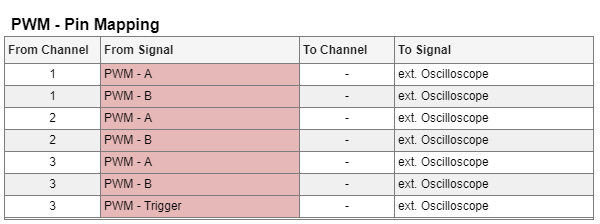

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_PWM_Symmetric';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

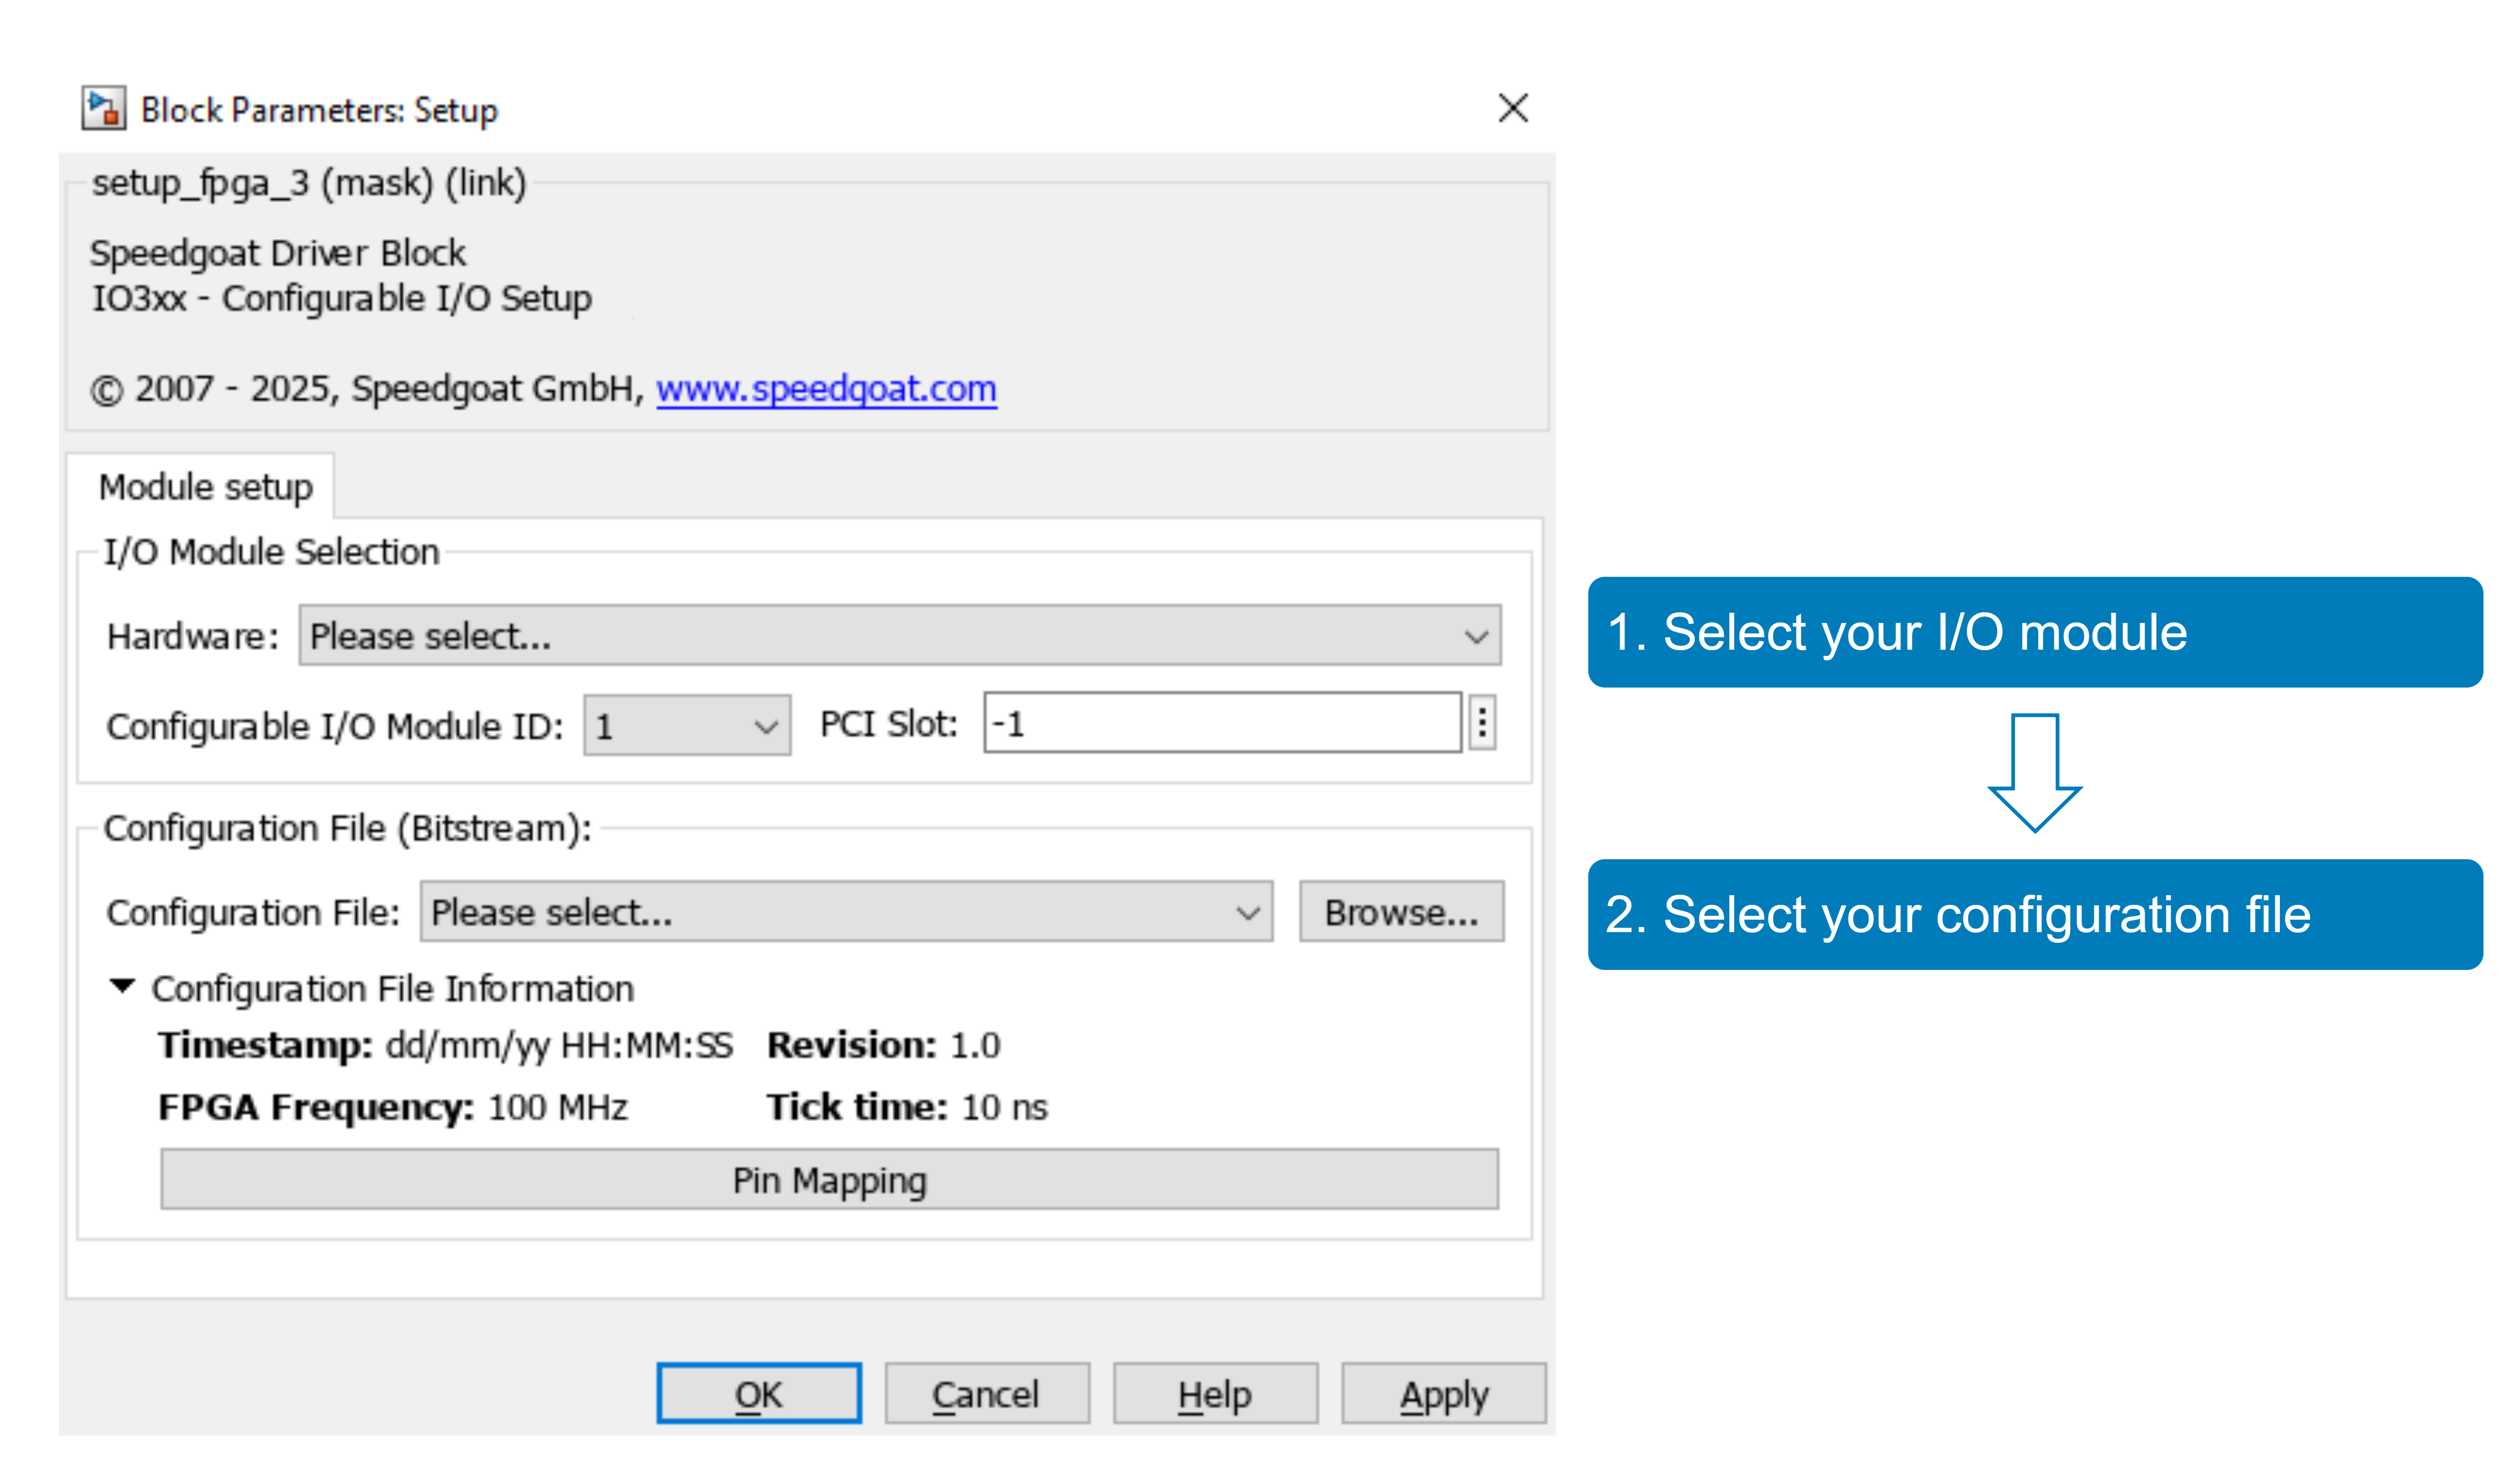

With the **Pin Mapping** button you can now check where the functionalities are located.

This model uses a sample time of 50 us. The PWM frequency is 20 kHz. The dead band is 1 us.

% specify sample times and deadband
Ts = 50e-6;
Tpwm = 50e-6;
Deadband = 1e-6;

## Model Description 

### PWM Generation

The model contains one instance of the PWM Generation v5 block. The block is assigned to PWM channels 1 to 3 (**Channel Vector** parameter) and is configured to generate three pairs of complementary symmetric PWM signals (A and B). All three PWM signals are synchronized. The same period length is defined in the block mask and all three channels are assigned by the same driver block instance. Note that different PWM channels assigned by different instances of the PWM Generation v5 driver block are not synchronized. There is no phase shift between the three channels.

- **PWM Phase Vector [s]: **0

- **Initial Period Vector [s]:** 50e-6

A symmetric PWM pattern is selected. Refer to the [PWM Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_pwm_usage_notes#refsect_pwm_trigger_output) for more information about this topic. The duty cycle of output B is the complement of output A. The protection unit within the PWM module forces output B to be low when output A is high in order to prevent A and B being high at the same time. This option is important if the duty cycles of signals A and B are altered separately. The dead band is set to 1 us.

- **PWM Pattern is:** Symmetric - PWM generation is centered around half the period

- **PWM B Output is:** The complement of PWM A output

- **AB-Output Protection:** B is forced off when A is on

- **Deadband Duration Vector [s]**: 1e-6 

The PWM Generation v5 module supports different modes for updating the internal comparators on the FPGA. The example model is configured to update the comparator inputs each time at the period start when the internal counter is reset. This leads to a PWM output signal which is symmetric around the period center as shown in the following figure.

- **Update PWM Generation:** At period starts

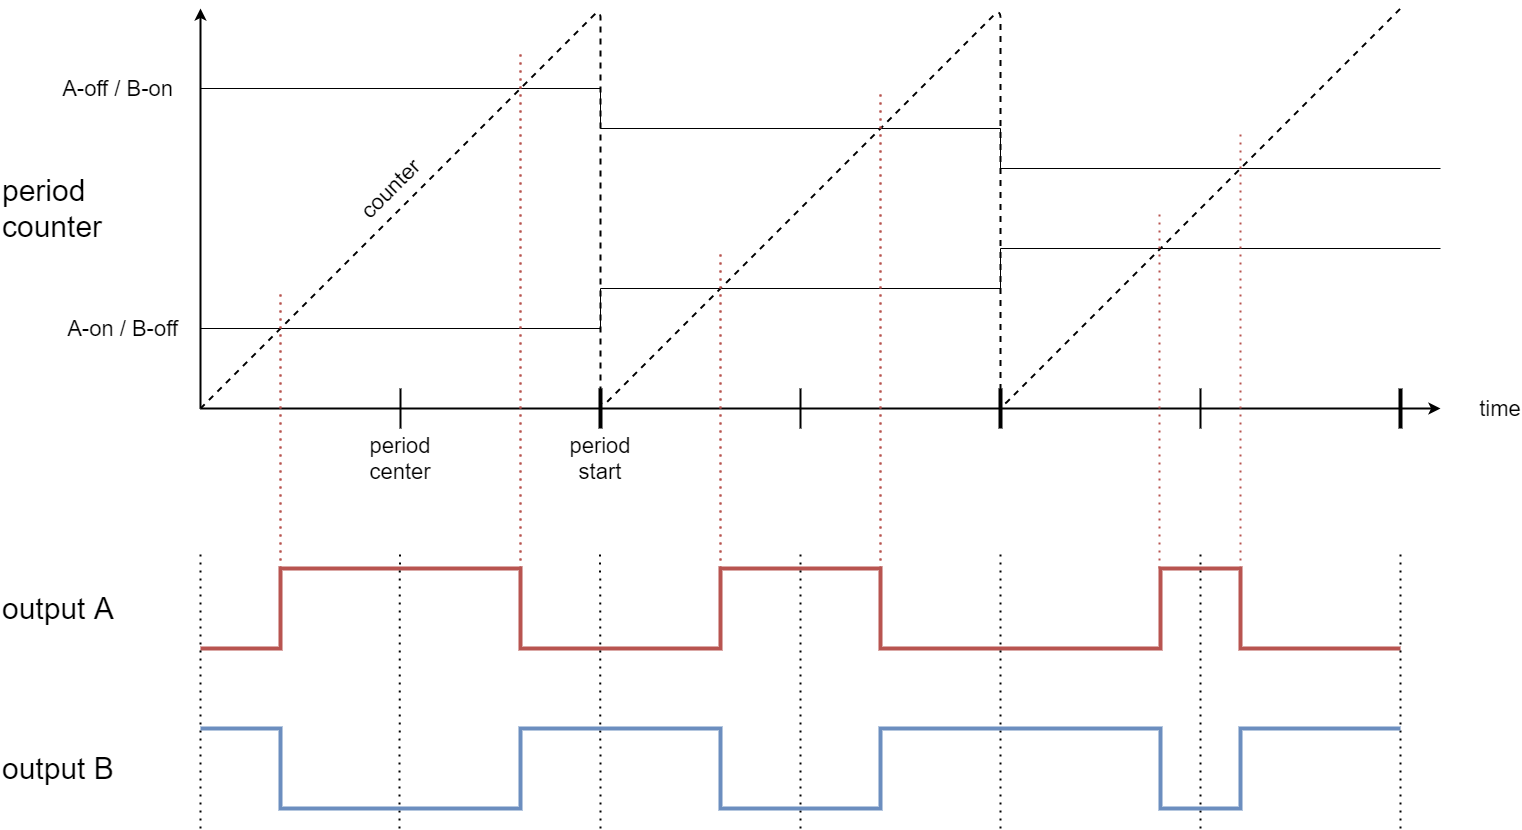

The PWM period is constant and equal to the **Initial Period Vector [s]** defined because the **Show Period Input Port** option is disabled (in the **Input Ports Configuration **tab). The duty cycle of the signal is directly defined by the **PWM A/ #B DC** input port which is connected to a three-phase sine wave signal. The signal range is between 0 and 1. The comparator values (A-on, A-off, B-on, B-off) are computed by the driver block based on the duty cycle input and period length. 

The trigger output is configured to generate a pulse with the length of 1 us at the center of each PWM period. This is defined in the **Triggering** tab of the block mask.

- **Trigger Duration Vector [s]:** 1e-6

- **Generate a Trigger at Period Start**

The PWM unit on the FPGA is only enabled when the model execution starts on the real-time system. The output states before model start and after model stop are defined in the **Offline State** tab:

- **PWM Output A is:** Low when PWM generation is stopped

- **PWM Output B is:** Low when PWM generation is stopped

It is important to define the pull resistor settings in the IO3xx Setup block mask in order to obtain well-defined I/O line states at model start and stop. The settings are located in the **Pull Resistor** tab.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode  

% Start the real-time application
tg.start;

### Check the Results

Run the model and connect an oscilloscope to the PWM output pins on the terminal board according to the pin mapping of your configuration file. The following figure shows signal A of the three PWM channels measured with an oscilloscope (channel 1: blue, channel 2: red, channel 3: green). The three signals are synchronous and symmetric around the period center. The trigger pulse of 1 us occurs right at the center of each period (yellow). 

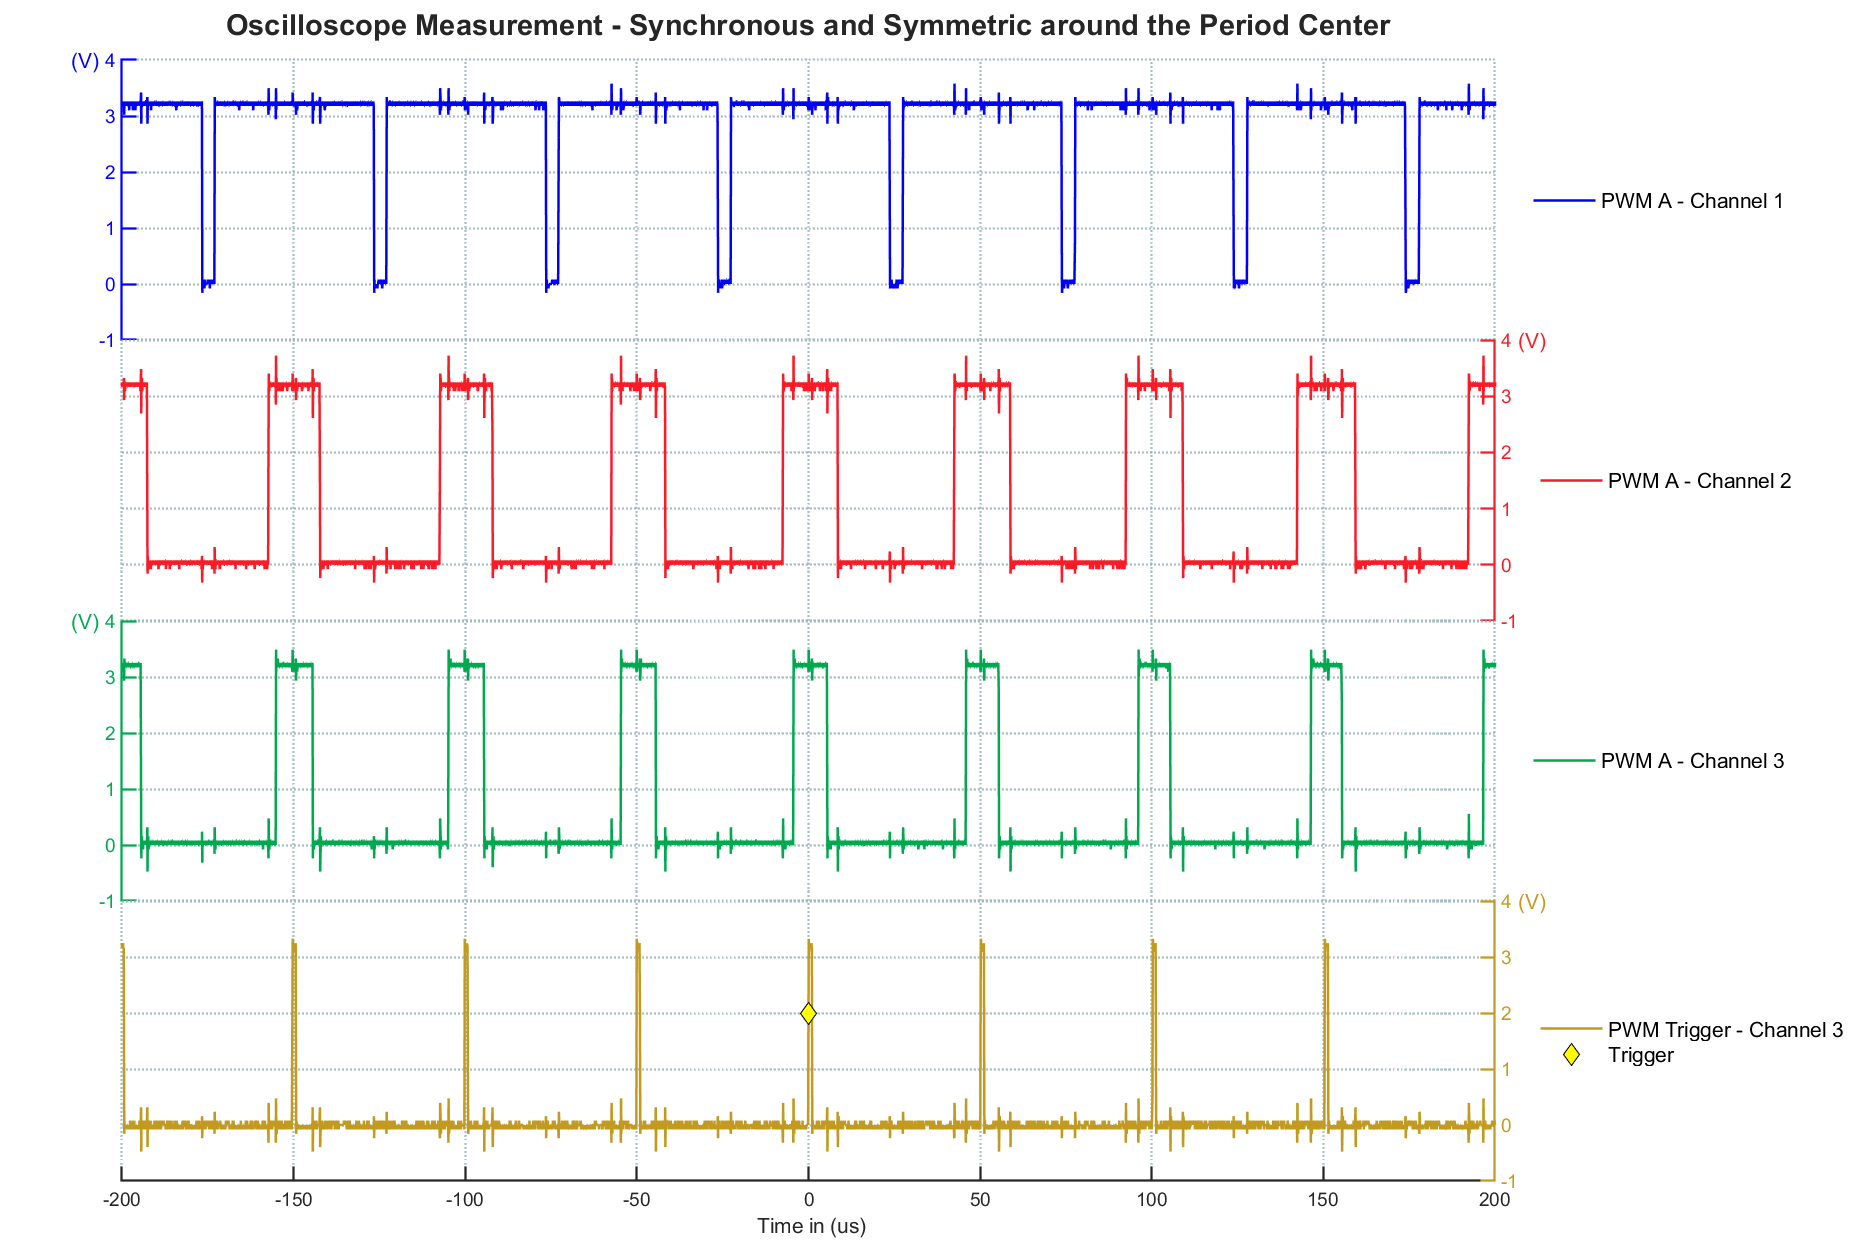

The next two graphs show signals A (blue) and B (red) of PWM channel 1. The signals are complementary with a dead band of 1 us. The trigger pulse occurs right at the center of each period (green).

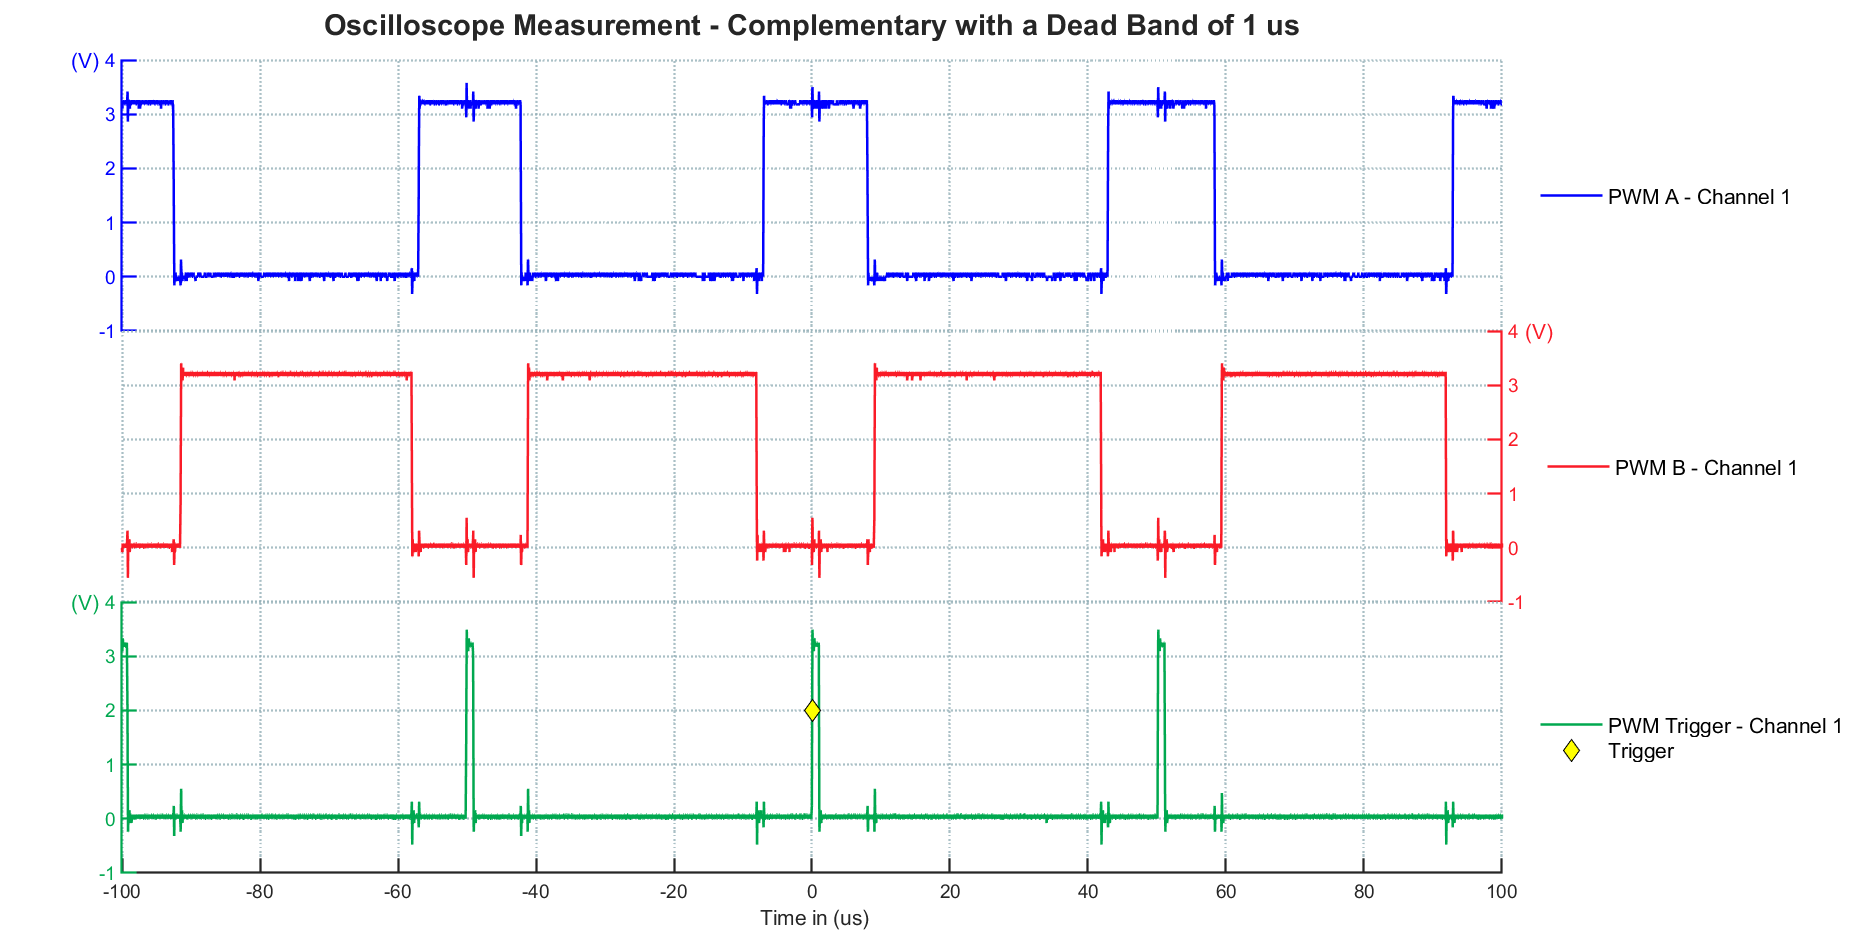

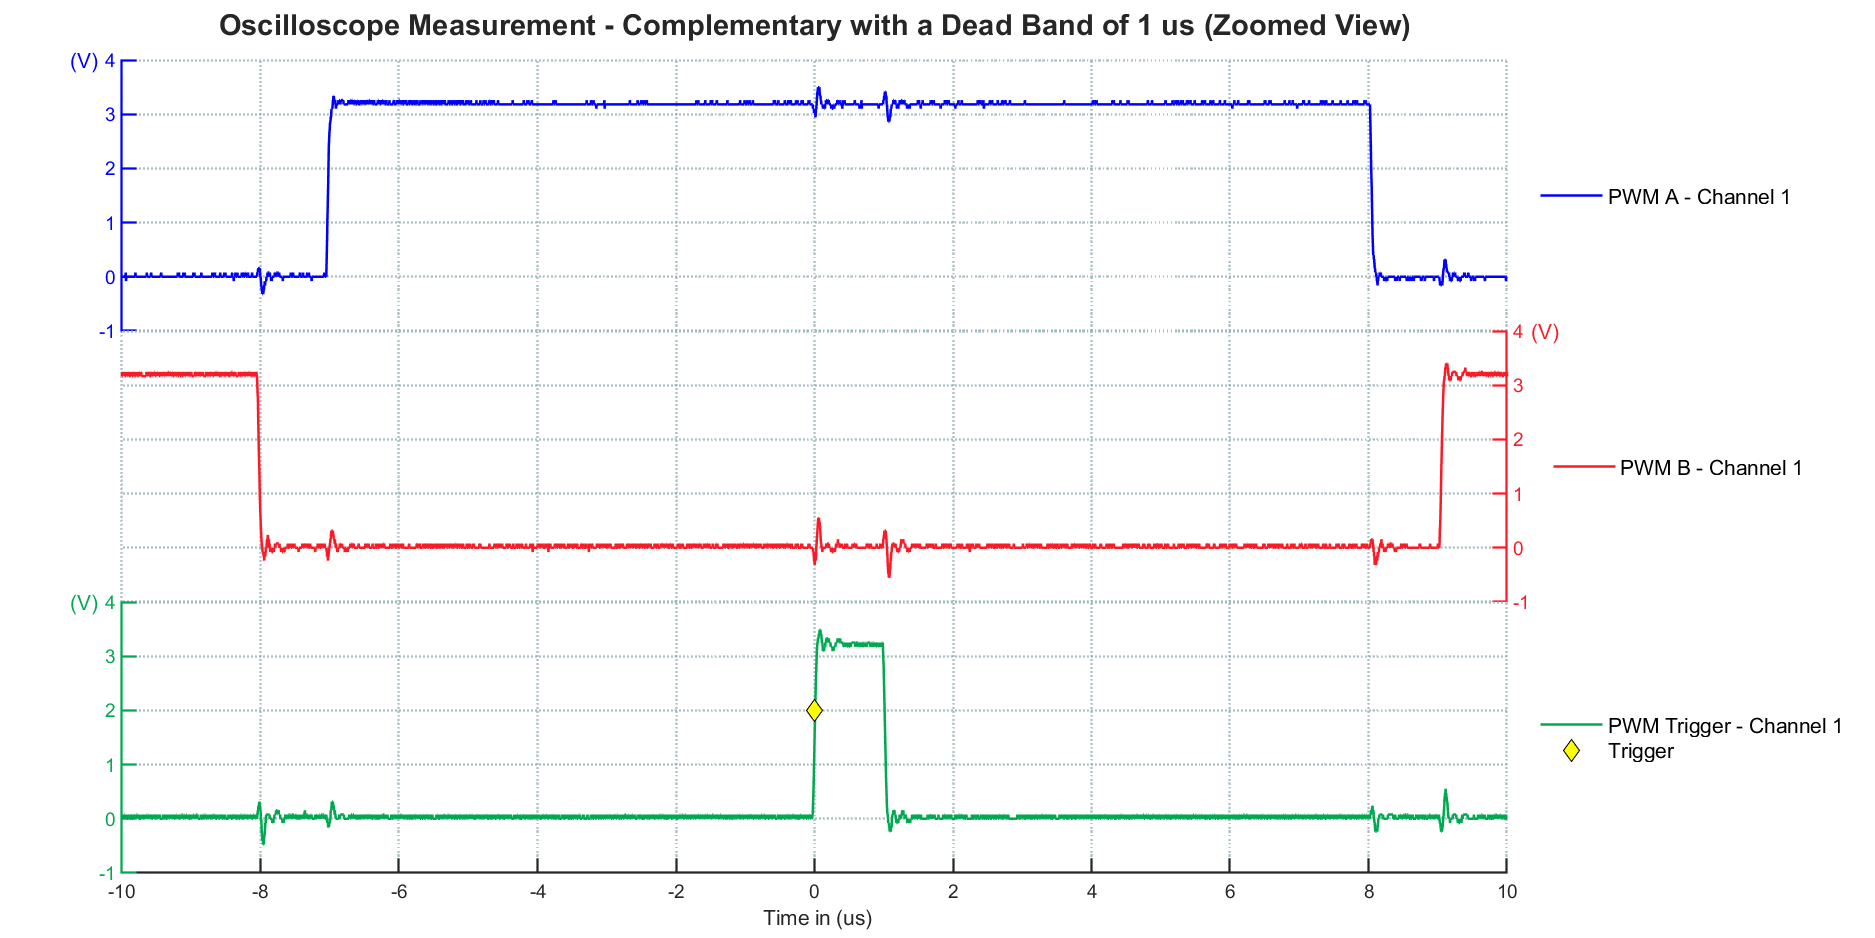

## Additional References

- [PWM documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_pwm)